arb = Arbotix('port', 'COM4', 'nservos', 5)

i = 4

 
arb = 
Arbotix chain on serPort COM4 (open)
 5 servos in chain                  


Servo_Speed = 40; %Defining speed of the servo

temp = arb.gettemp(); %give id like "5" if you want specific motor information
str_temp = ['The temperature for all the motors are following: ' num2str(temp)];
disp(str_temp);

The temperature for all the motors are following: 33  58  50  35  34


`arb.setpos(id, pos,speed)` sets the goal position of the servomotor id to pos radians. The motor will then start moving to the goal position.

sets the positions and speeds of servos 1-N to corresponding elements in the vectors pos and speed respectively.

rad = deg2rad(pi/2);
arb.setpos(1,0,Servo_Speed); %Set Motor 1, The base. -0.3 min, 0.5 max
arb.setpos(2,1.8,Servo_Speed); % 1.7 to 1.8, Set Motor 2. -1 deg min, +1 max
arb.setpos(3,0, Servo_Speed); %Set Motor 3 %-1 deg. -0.5 deg mind,-1 deg max 
arb.setpos(4,0, Servo_Speed); %Set Motor 4 % in min -0.5 deg and in max -2deg
pos = -2;
arb.setpos(5,pos); %pos radians, Speed optional, accepts between 0 to 1023, 0 is max. arb.setpos(id, pos,speed)
pos = arb.getpos() %Range constrainted to -150 to 150

pos =    -0.0051    1.7948    0.0153   -0.0102   -1.9993


arb.relax([], false); %true relaxed, false provides torque


%Finding new positions
pos = arb.getpos(); %Range constrainted to -150 to 150
pos_deg = rad2deg(pos);
str_pos = ['angles for all the motors: ' num2str(pos)]; %In radians
str_pos_deg = ['angles for all the motors: ' num2str(pos_deg)]; %In radians
disp(str_pos);

angles for all the motors: 


disp(str_pos_deg);

angles for all the motors: 


arb.relax(id, status) causes the servo id to enter zero-torque (relaxed) state if status argument is missing or TRUE. 

If the status is FALSE, then the servo starts providing torque.

To relax all motors arb.relax() or arb.relax([]) can be used, and the relaxed mode can be ended with arb.relax([],FALSE).

arb.relax([], false); %true relaxed, false provides torque


#### Task 5.9

jointAngles = [pi/2,0,0,0];
[x, y, z, R, theta, phi] = pincherFK(jointAngles)

x = 1.9487e-17

y = 0.3182

z = 0.0449

R =     0.0000   -0.0000    1.0000
    1.0000    0.0000   -0.0000
         0    1.0000    0.0000


theta = -6.1232e-17

phi = 1.5708

--------------------
Robot: (4 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2     revolute            body1(1)   body3(3)  
   3        body3         jnt3     revolute            body2(2)   body4(4)  
   4        body4         jnt4     revolute            body3(3)   
--------------------


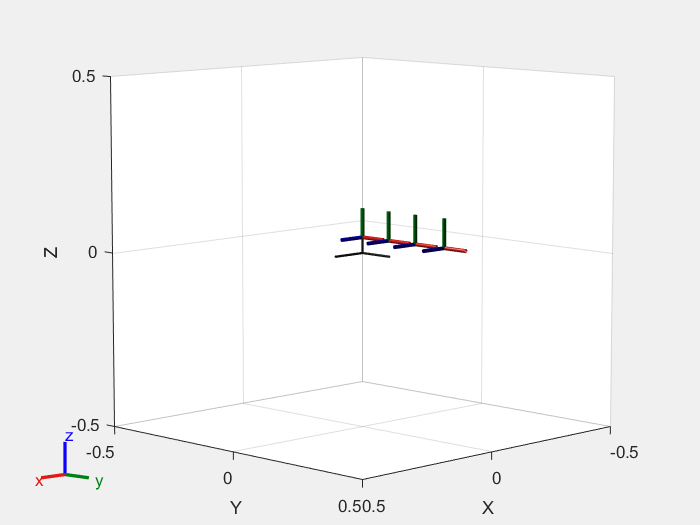

The position of end-effector is:
X: 1.9487e-17
Y: 0.31825
Z: 0.04495
 
R: 


ans =     0.0000   -0.0000    1.0000
    1.0000    0.0000   -0.0000
         0    1.0000    0.0000


 
The orientation angle is given with respect to the x-axis of joint 2:
Angle: 0 degrees.


pinchermodel2(jointAngles)

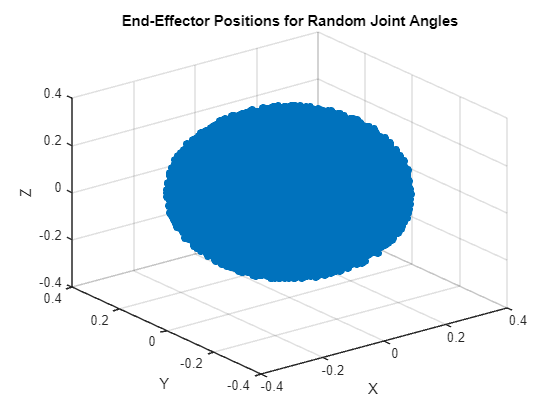

joint_angles_random = zeros(1, 4);
num_points = 100000;

% Initialize arrays to store x, y, z coordinates
x_points = zeros(1, num_points);
y_points = zeros(1, num_points);
z_points = zeros(1, num_points);

for i = 1:num_points
    for j = 1:4
        joint_angles_random(i, j) = randi([-150, 150]);
    end
    joint_angles_random(i, 2) = joint_angles_random(i, 2) + 90;
end
joint_angles_random(2) = joint_angles_random(2) + 90;


%disp(joint_angles_random); % Display the random array
[x_points(i), y_points(i), z_points(i), R, theta, phi] = pincherFK(joint_angles_random);
% Compute end-effector positions for all points
for i = 1:num_points
    [x_points(i), y_points(i), z_points(i), ~, ~, ~] = pincherFK(joint_angles_random(i, :));
end


% Plot the points in 3D space
scatter3(x_points, y_points, z_points, 'filled');
xlabel('X');
ylabel('Y');
zlabel('Z');
title('End-Effector Positions for Random Joint Angles');

### Task 5.10 (Creating the dh2servo function to be used)

%Creating jointAngles array consisting of our DH angles. 
DH_JointAngle1 = -150;
DH_JointAngle2 = 00;
DH_JointAngle3 = 150;
DH_JointAngle4 = 90;

% Prompt the user for joint angles
% DH_JointAngle1 = input('Enter DH Joint Angle 1 in degrees: ');
% DH_JointAngle2 = input('Enter DH Joint Angle 2 in degrees: ');
% DH_JointAngle3 = input('Enter DH Joint Angle 3 in degrees: ');
% DH_JointAngle4 = input('Enter DH Joint Angle 4 in degrees: ');

jointAngles = [DH_JointAngle1, DH_JointAngle2, DH_JointAngle3, DH_JointAngle4];
[servoJointAngles,errorCode] = dh2servo(jointAngles);

DH Joint angles are: -150    0  150   90
Servo Joint angles are: -2.618           0       2.618      1.5708
In degrees without pi to pit transform, Servo Joint angles are: -150   90  150   90


if (errorCode == 1)
    servoJointAngles = []; % Empty array for servo joint angles
    error('Joint angles are outside the allowable range of [-150, 150] degrees')
end


% arb.setpos([1,2,3,4],[-0.5859    0.9849   -0.5859   -0.5859],Servo_Speed);
 arb.setpos(1,-0.5859 );
  arb.setpos(1,0.9849);
   arb.setpos(1,-0.5859);
    arb.setpos(1,-0.5859);